# Fundamentals of Linear Control

**Mauricio de Oliveira**

*Supplemental material **for Chapter 8*

## Before You Start

In this script you will perform calculations with transfer-functions. In addition to the commands already used, the following MATLAB commands will be used:

- sim, to simulate a nonlinear model using simulink.

 You will also use the following auxiliary commands:

- rectangle, to plot circles.

## 8.1 Closed-Loop Stability and Performance

Create tf objects to represent the pendulum linearized about the stable and the unstable equlibria:

% Pendulum parameters
m = 0.5

m = 0.5000

l = 0.3

l = 0.3000

r = l/2

r = 0.1500

b = 0

b = 0

g = 9.8

g = 9.8000

J = m*l^2/12

J = 0.0038

Jr = (J+m*r^2)

Jr = 0.0150


% models linearized around equilibria
Gpi = tf(1/Jr, [1, b/Jr, -m*r*g/Jr])


Gpi =
 
   66.67
  --------
  s^2 - 49
 
Continuous-time transfer function.



G0 = tf(1/Jr, [1, b/Jr, m*r*g/Jr])


G0 =
 
   66.67
  --------
  s^2 + 49
 
Continuous-time transfer function.



wn = 7;

Create tf objects to represent the controllers $C_6$ and $C_7$ from Sections 6.5 and 7.8:

% C6 controller
C6 = zpk([-6.855, -0.9573], [0, -21], 3.8321)


C6 =
 
  3.8321 (s+6.855) (s+0.9573)
  ---------------------------
           s (s+21)
 
Continuous-time zero/pole/gain model.




% C7 controlller
z1 = 1;
z2 = 5;
pc = 11;
C7 = tf(conv([1 z1],[1 z2]),conv([1 0],[1 pc]));
K = 2/abs(freqresp(C7,wn));
C7 = zpk(K * C7)


C7 =
 
  3.0009 (s+5) (s+1)
  ------------------
       s (s+11)
 
Continuous-time zero/pole/gain model.



Calculate the closed-loop sensitivity transfer-functions with controller $C_6$:

S6 = feedback(1,Gpi*C6)


S6 =
 
              s (s+7) (s-7) (s+21)
  ---------------------------------------------
  (s^2 + 9.454s + 22.37) (s^2 + 11.55s + 74.95)
 
Continuous-time zero/pole/gain model.



damp(S6)

                                                                       
         Pole              Damping       Frequency      Time Constant  
                                       (rad/seconds)      (seconds)    
                                                                       
 -4.73e+00 + 1.54e-01i     9.99e-01       4.73e+00         2.12e-01    
 -4.73e+00 - 1.54e-01i     9.99e-01       4.73e+00         2.12e-01    
 -5.77e+00 + 6.45e+00i     6.67e-01       8.66e+00         1.73e-01    
 -5.77e+00 - 6.45e+00i     6.67e-01       8.66e+00         1.73e-01    


and with controller $C_7$:

S7 = feedback(1,Gpi*C7)


S7 =
 
             s (s+7) (s+11) (s-7)
  -------------------------------------------
  (s^2 + 5.47s + 8.942) (s^2 + 5.53s + 111.9)
 
Continuous-time zero/pole/gain model.



damp(S7)

                                                                       
         Pole              Damping       Frequency      Time Constant  
                                       (rad/seconds)      (seconds)    
                                                                       
 -2.73e+00 + 1.21e+00i     9.15e-01       2.99e+00         3.66e-01    
 -2.73e+00 - 1.21e+00i     9.15e-01       2.99e+00         3.66e-01    
 -2.77e+00 + 1.02e+01i     2.61e-01       1.06e+01         3.62e-01    
 -2.77e+00 - 1.02e+01i     2.61e-01       1.06e+01         3.62e-01    


Calculate the loop transfer-function with $C_6$:

L6 = Gpi*C6


L6 =
 
  255.47 (s+6.855) (s+0.9573)
  ---------------------------
     s (s-7) (s+7) (s+21)
 
Continuous-time zero/pole/gain model.



and with $C_7$:

L7 = Gpi*C7


L7 =
 
   200.06 (s+5) (s+1)
  --------------------
  s (s-7) (s+7) (s+11)
 
Continuous-time zero/pole/gain model.



Plot the combined frequency response:

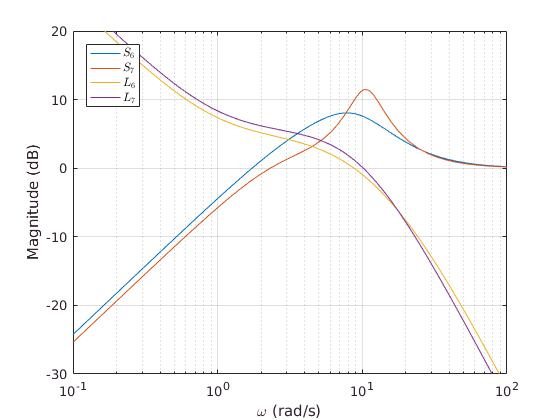

xl = [-1, 2];
yl1 = [-30, 20];
yl2 = [0, 270];

[magS7,phsS7,w] = bode(S7, {10^xl(1), 10^xl(2)});
[magS6,phsS6] = bode(S6, w);

[magL6,phsL6] = bode(L6, w);
[magL7,phsL7] = bode(L7, w);

% Fix phases
phsL6 = phsL6 + 360;
phsL7 = phsL7 + 360;

xl = [-1 2];
yl1 = [-30 20];
yl2 = [0 270];

% Fig. 8.2 (a):
figure()

hline = semilogx(w, 20*log10([magS6(:)'; magS7(:)'; magL6(:)'; magL7(:)']));
grid on

xlim(10.^xl);
ylim(yl1);

set(gca, 'YTick', [-30 -20 -10 0 10 20]);

l = legend('$S_6$', '$S_7$', '$L_6$', '$L_7$', 'Location', 'NorthWest');
set(l, 'interpreter', 'latex');
ylabel('Magnitude (dB)');
xlabel('\omega (rad/s)');

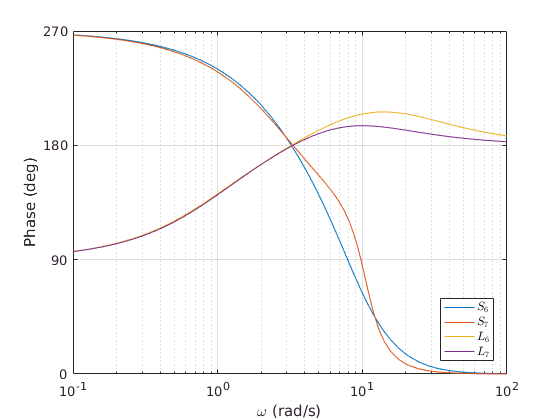


% Fig. 8.2 (b):
figure()

hline = semilogx(w, ([phsS6(:)'; phsS7(:)'; phsL6(:)'; phsL7(:)']));
grid on

xlim(10.^xl);
ylim(yl2);

set(gca, 'YTick', [0 90 180 270 360]);

l = legend('$S_6$', '$S_7$', '$L_6$', '$L_7$', 'Location', 'SouthEast');
set(l, 'interpreter', 'latex');
ylabel('Phase (deg)');
xlabel('\omega (rad/s)');

## 8.4 Control of the Simple Pendulum - Part III

Create tf objects to represent the controller $C_8$:

% C8 controller
z1 = 1;
z2 = 3;
pc = 10.5;
C8 = tf(conv([1 z1],[1 z2]),conv([1 0],[1 pc]))


C8 =
 
  s^2 + 4 s + 3
  -------------
  s^2 + 10.5 s
 
Continuous-time transfer function.



K = 2/abs(freqresp(C8,wn));
C8 = zpk(K * C8)


C8 =
 
  3.2807 (s+3) (s+1)
  ------------------
      s (s+10.5)
 
Continuous-time zero/pole/gain model.



Compare frequency response of the controllers:

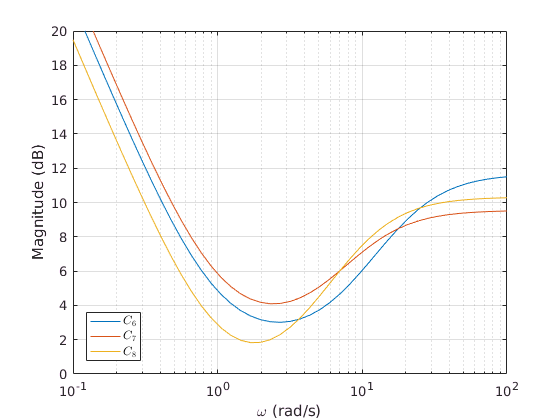

% Bode plots
xl = [-1 2];

[magC6,phsC6,w] = bode(C6, {10^xl(1), 10^xl(2)});
[magC7,phsC7] = bode(C7, w);
[magC8,phsC8] = bode(C8, w);

% Fig. 8.8:
figure()

yl1 = [0 20];

hline = semilogx(w, 20*log10([magC6(:)'; magC7(:)'; magC8(:)']));
grid on

xlim(10.^xl);
ylim(yl1);

l = legend('$C_6$', '$C_7$', '$C_8$', ...
           'Location', 'SouthWest'); 
set(l, 'interpreter', 'latex');
ylabel('Magnitude (dB)');
xlabel('\omega (rad/s)');

Calculate the loop transfer-function with $C_8$:

L8 = Gpi*C8


L8 =
 
    218.71 (s+3) (s+1)
  ----------------------
  s (s-7) (s+7) (s+10.5)
 
Continuous-time zero/pole/gain model.



Plot the combined frequency response:

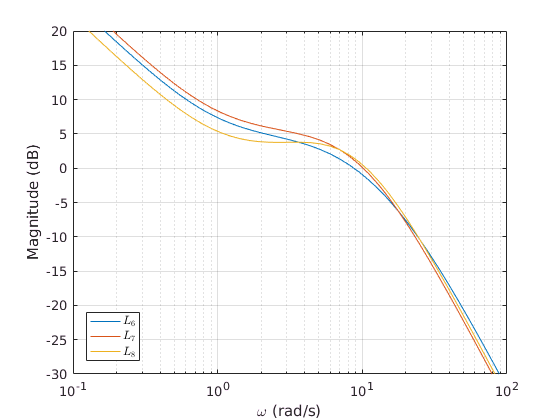

[magL6,phsL6,w] = bode(L6, {10^xl(1), 10^xl(2)});
[magL7,phsL7] = bode(L7, w);
[magL8,phsL8] = bode(L8, w);

% Fix phases
phsL6 = phsL6 + 360;
phsL7 = phsL7 + 360;
phsL8 = phsL8 + 360;

% Fig. 8.9a:
figure()

yl2 = [-30 20];

hline = semilogx(w, 20*log10([magL6(:)'; magL7(:)'; magL8(:)']));
grid on

xlim(10.^xl);
ylim(yl2);

l = legend('$L_6$', '$L_7$', '$L_8$', ...
           'Location', 'SouthWest'); 
set(l, 'interpreter', 'latex');
ylabel('Magnitude (dB)');
xlabel('\omega (rad/s)');

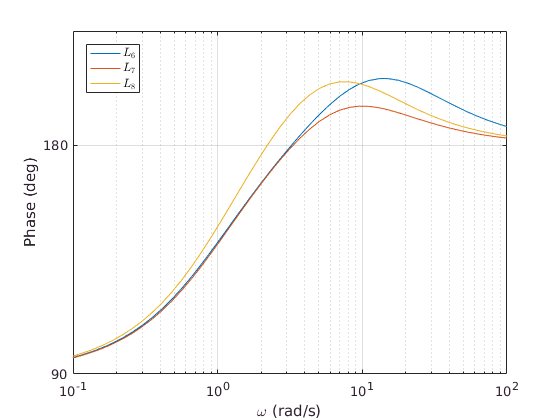


% Fig. 8.9b:
figure()

yl2 = [90 225];

hline = semilogx(w, ([phsL6(:)'; phsL7(:)'; phsL8(:)']));
grid on

xlim(10.^xl);
ylim(yl2);

set(gca, 'YTick', [0 90 180 270 360]);

l = legend('$L_6$', '$L_7$', '$L_8$', ...
           'Location', 'NorthWest'); 
set(l, 'interpreter', 'latex');
ylabel('Phase (deg)');
xlabel('\omega (rad/s)');

Create auxiliary model for robust analysis:

a1 = b/Jr

a1 = 0

a2 = m*g*r/Jr

a2 = 49

b2 = 1/Jr

b2 = 66.6667

F = tf(1, [1 a1 0])


F =
 
   1
  ---
  s^2
 
Continuous-time transfer function.



with controller $C_6$:

G6 = -a2*feedback(F,b2*C6)


G6 =
 
                -49 s (s+21)
  -----------------------------------------
  (s+12.48) (s+0.9461) (s^2 + 7.573s + 142)
 
Continuous-time zero/pole/gain model.



with controller $C_6$:

G7 = -a2*feedback(F,b2*C7)


G7 =
 
                 -49 s (s+11)
  ------------------------------------------
  (s+6.089) (s+0.988) (s^2 + 3.923s + 166.3)
 
Continuous-time zero/pole/gain model.



with controller $C_6$:

G8 = -a2*feedback(F,b2*C8)


G8 =
 
                -49 s (s+10.5)
  -------------------------------------------
  (s+3.559) (s+0.9797) (s^2 + 5.961s + 188.2)
 
Continuous-time zero/pole/gain model.



and evaluate the norm $H_\infty$ for each transfer-function:

norm(G6,inf)

ans = 0.8188

norm(G7,inf)

ans = 1.1687

norm(G8,inf)

ans = 0.7600

which confirm that the small gain theorem can prove that the controllers $C_6$ and $C_8$ can stabilize the nonlinear model of the simple pendulum, but not $C_7$.

Repeat the robustness study this time using the circle criterion by verifying if the Nyquist diagram of the transfer-functions $G_6$, $G_7$ and $G_8$ are in the circle $C(-0.22,1)$:

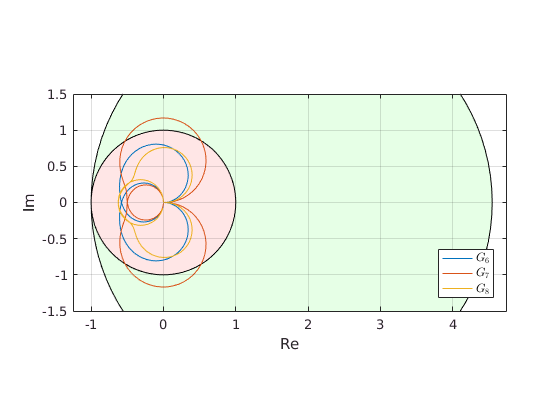

% Nyquist diagrams
eps0 = 0.02;
offset = 0.1;

[re,im] = nyquist(G6, {eps0,1e2});
b6 = re(:) + j*im(:);

[re,im] = nyquist(G7, {eps0,1e2});
b7 = re(:) + j*im(:);

eps0 = 0.1;
offset = 0.1;

[re,im] = nyquist(G8, {eps0,1e2});
b8 = re(:) + j*im(:);

% Unit circles C(-1,1)
t = 0 : 0.1 : 2*pi;
circ1 = cos(t) + j*sin(t);

% Circle C(-0.22,1)
alpha = -0.22;
beta = 1;
cc = -(1/alpha+1/beta)/2;
rr = abs(-1/alpha+1/beta)/2;
circ2 = cc + rr*(cos(t) + j*sin(t));

% Fig. 8.15:
figure()

xl = [-1.25 4.75];
yl = 1.2*[-1.25 1.25];

plot(real([b6; b6]), imag([b6; -b6]), ...
     real([b7; b7]), imag([b7; -b7]), ...
     real([b8; b8]), imag([b8; -b8]))

% The following commands plot the circles
% in spite of the name rectangle :)
h = rectangle('Position',[-1,-1,2,2], 'Curvature',[1,1], ...
          'FaceColor', 0.1*[1 0 0] + .9*[1 1 1]);
uistack(h, 'bottom')
h = rectangle('Position',[-1,-rr,2*rr,2*rr], 'Curvature',[1,1], ...
              'FaceColor', 0.1*[0 1 0] + .9*[1 1 1]);
uistack(h, 'bottom')

l = legend('$G_6$', '$G_7$', '$G_8$', 'Location', 'SouthEast');
set(l, 'interpreter', 'latex');

xlim(xl)
ylim(yl)

xlabel('Re');
ylabel('Im');

grid on
set(gca, 'layer', 'top')

pbaspect([1 diff(ylim)/diff(xlim) 1]);

Alternatively calculate the parameters (8.16):

aa = (alpha+beta)/2

aa = 0.3900

bb = (beta-alpha)/2

bb = 0.6100

and verify the algebraic condition (8.18):

norm((bb/aa)*feedback(aa*G6,1),inf)

ans = 0.5641

norm((bb/aa)*feedback(aa*G7,1),inf)

ans = 0.7174

norm((bb/aa)*feedback(aa*G8,1),inf)

ans = 0.5022

which should all be less than one.

**Be patient, this step may t****ake a while!**

Repeat this study varying the damping parameter $b$:

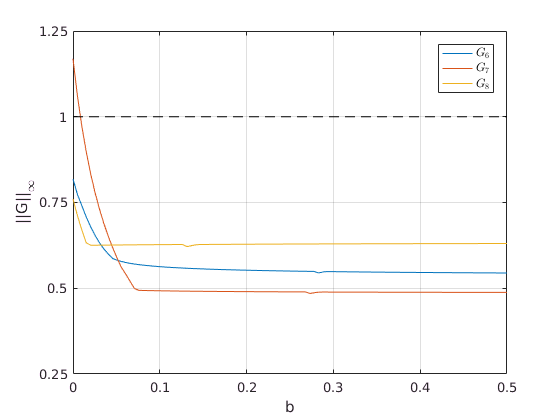

% Damping study

bs = linspace(0, 0.5, 100);
Gs = zeros(3,length(bs));

i = 1;
for bb = bs

  % model for uncertainty feedback
  aa1 = bb/Jr;
  FF = tf(1, [1 aa1 0]);

  GG6 = -a2*feedback(FF,b2*C6);
  GG7 = -a2*feedback(FF,b2*C7);
  GG8 = -a2*feedback(FF,b2*C8);
  Gs(:,i) = [norm(GG6,inf); norm(GG7,inf); norm(GG8,inf)];

  i = i + 1;

end

xl = [bs(1) bs(end)];
yl = [.25 1.25];

% Fig. 8.11:
figure()

plot(bs, Gs, ...
     xl, [1 1], 'k--');
grid on

xlim(xl);
ylim(yl);

set(gca, 'YTick', [.25 0.5 0.75 1 1.25]);
set(gca, 'XTick', [0 0.1 0.2 0.3 0.4 0.5]);

l = legend('$G_6$', '$G_7$', '$G_8$', 'Location', 'NorthEast');
set(l, 'interpreter', 'latex');
ylabel('||G||_\infty');
xlabel('b');

Select a controller for simulation:

ctr = tf(C7) % make sure it is a tf object


ctr =
 
  3.001 s^2 + 18.01 s + 15
  ------------------------
         s^2 + 11 s
 
Continuous-time transfer function.



and simulate using the simulink model

SimplePendulumWithFeedback

This model takes some variables from the workspace:

thetaBar = pi/2 - pi/4;
theta0 = pi/2;
num = ctr.num{1};
den = ctr.den{1};

You can interact with the simulation on the GUI interface or using the command line interface. The following will simulate the closed-loop system for 10 seconds:

T = 10

T = 10

sim('SimplePendulumWithFeedback', T)

The following will recreate Fig. 8.12:

T1 = 4

T1 = 4

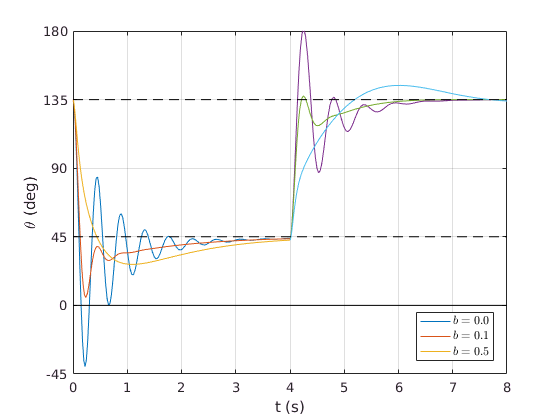

thetaBar1 = pi/2 - pi/4;
theta0 = pi/2 + pi/4;

bs = [0 .1 .5];

N = length(bs);
y1 = cell(1,N);
t1 = cell(1,N);
i = 1;
for b = bs

  thetaBar = thetaBar1;

  [ti,x,yi] = sim('SimplePendulumWithFeedback', T1, simset('OutputVariables', 'ty', 'RelTol', 1e-5));
  t1{i} = ti;
  y1{i} = yi;

  i = i + 1;

end

leg = [ones(N, 1) * '$b = ' num2str(bs','%2.1f') ones(N, 1) * '$'];

thetaBar2 = pi/2 + pi/4;
T2 = T1;

N = length(bs);
y2 = cell(1,N);
t2 = cell(1,N);
i = 1;
for b = bs

  thetaBar = thetaBar2;
  theta0 = y1{i}(end);

  [ti,x,yi] = sim('SimplePendulumWithFeedback', T2, ...
                   simset('OutputVariables', 'ty', 'RelTol', 1e-5));
  t2{i} = ti;
  y2{i} = yi;

  i = i + 1;

end

Y1 = [t1; cellfun(@(x) (180/pi)*x, y1, 'UniformOutput', false)];

Y2 = [cellfun(@(x) x+T1, t2, 'UniformOutput', false); cellfun(@(x) (180/pi)*x, y2, 'UniformOutput', false)];

yl = [-45 180];

plot(Y1{:}, ...
     Y2{:}, ...
     [0 T1+T2], (180/pi)*thetaBar1*[1 1], 'k--', ...
     [0 T1+T2], (180/pi)*thetaBar2*[1 1], 'k--', ...
     [0 T1+T2], (180/pi)*0*[1 1], 'k-')

l = legend(leg, 'Location', 'SouthEast');
set(l, 'interpreter', 'latex');

ylim(yl)

xlabel('t (s)')
ylabel('\theta (deg)')
grid on

set(gca, 'YTick', [-45 0 45 90 135 180]);


b = 0 % set b back 0

b = 0